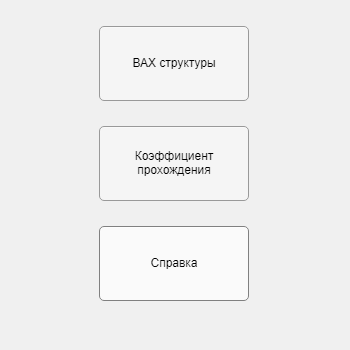

menus;

function [U1,U]=Structure(cmesh1,ns,nk1,nk2,UB,V)%Функция задания смещения%
U1=V*[cmesh1*ones(1,nk1) linspace(cmesh1,-cmesh1,ns) -cmesh1*ones(1,nk2)];
U=U1';
U1=U1'+UB;
end

%Функция для задания меню%
function menus(~)
fig=uifigure('Name','Меню');
fig.Position(3:4)=[350 350];

fb=uibutton(fig,'ButtonPushedFcn', @(fb,fig) fbbutpush(fb,fig));
fb.Position=[100 250 150 75];
fb.Text='ВАХ структуры';

fs=uibutton(fig,'ButtonPushedFcn', @(fs,fig) fsbutpush(fs,fig));
fs.Position=[100 150 150 75];
fs.Text=['Коэффициент', newline,'прохождения'];

ft=uibutton(fig,'ButtonPushedFcn', @(fs,fig) ftbutpush(fs,fig));
ft.Position=[100 50 150 75];
ft.Text='Справка';
end

%Функция обратной связи первой кнопки меню(подсчет ВАХ)%
function fbbutpush(~,~)
[Ef,IE,NE,E,~,hstruct,t0,Nk1,Nk2,NS,Np,cmesh,kT]=constantt;
%Нулевые значения матриц тока и коэффициента прохождения%
TE1=zeros(1,101);
IBAX=zeros(1,100);
%Вызов функции подсчета гамильтониана и структуры%
[UB,H]=Hamiltonian(t0,Np,NS,Nk1,Nk2,hstruct);
NV=100;
%Промежуток задания потенциала%
Vt=linspace(0, 0.85);
for cV=1:NV
    V=Vt(cV);
    %Расчет химического потенциала контактов%
    mu1=Ef+(V/2);
    mu2=Ef-(V/2);
    %Смещение потенциала%
    [~,U]=Structure(cmesh,NS,Nk1,Nk2,UB,V);
    %Разница энергий для расчета тока%
    dE=E(2)-E(1);
    %Распределение Ферми для 2ух контактов%
    f1=1./(1+exp((E-mu1)./kT));
    f2=1./(1+exp((E-mu2)./kT));
    I=0;%Начальное значение тока%
for k=1:NE
    %Вызов функции расчета коэффициента прохождения%
    TE1(k)=Cycle(Np,E,k,U,UB,t0,H);
    %Подсчет плотности тока %
    I=I+(dE*IE*TE1(k)*(f1(k)-f2(k)));
end
IBAX(cV)=I;
end
figure('Position',[250 250 500 400],'Name','ВАХ','NumberTitle','off')
plot(Vt,IBAX);
grid on
title('ВАХ');
xlim([0 0.85])
xlabel('Напряжение, В');
ylabel('Ток, А');
end

%Цикл подсчета функции Грина%
function TE=Cycle(Np,E,k,U,UB,t0,H)
%Подсчет матрицы собственно-энергетических функций%
Sigm1=zeros(Np);
Sigm2=zeros(Np); 
zplus=1i*1e-12;
kgr=1-((E(k)+zplus-U(1)-UB(1))/(2*t0));
ka=acos(kgr);
Sigm1(1,1)=-t0*exp(1i*ka);
gam1=1i*(Sigm1-Sigm1');
kgr=1-((E(k)+zplus-U(Np)-UB(Np))/(2*t0));
ka=acos(kgr);
Sigm2(Np, Np)=-t0*exp(1i*ka);
%Уширение%
gam2=1i*(Sigm2-Sigm2');
%Функция Грина%
G=inv((E(k)+zplus)*eye(Np)-H-diag(U)-Sigm1-Sigm2);
%Подсчет коэффициента прохождения%
TE=real(trace(gam1*G*gam2*G'));
end

%Функция обратной связи второй кнопки меню%
function fsbutpush(~,~)
[~,~,NE,E,xcor,hstruct,t0,Nk1,Nk2,NS,Np,cmesh,~]=constantt;
%Подсчет коэффицента прохождения%
TE1=zeros(1,101);
[UB,H]=Hamiltonian(t0,Np,NS,Nk1,Nk2,hstruct);
V=cmesh;
[U1,U]=Structure(cmesh,NS,Nk1,Nk2,UB,V);
for k=1:NE
    TE1(k)=Cycle(Np,E,k,U,UB,t0,H);
end
%Графики%
figure('Position',[250 250 1100 500],'Name','Коэффициент прохождения','NumberTitle','off');
hold on
subplot(1,3,2);
plot(TE1,E);
grid on
ylim([-cmesh/2-0.05 max(UB)+cmesh/2+0.15]);
title('Коэффициент прохождения');
xlabel('Коэффициент прохождения');
ylabel('Энергия, эВ');

subplot(1,3,3);
semilogx(TE1,E);
grid on
ylim([-cmesh/2-0.05 max(UB)+cmesh/2+0.15]);
title('Коэффициент прохождения (log(E))');
xlabel('Коэффициент прохождения');
ylabel('Энергия, эВ');

subplot(1,3,1);
plot(xcor,U1);
grid on
ylim([-cmesh/2-0.05 max(UB)+cmesh/2+0.15]);
xlim([1 13]);
hold off
title('Cтруктура');
xlabel('Координата, нм');
ylabel('Энергия, эВ');
%Слайдер и вывод значения смещения%
uicontrol('style','slider','Position',[20 10 25 480],...
    'min',0,'max',0.5,'SliderStep',[0.05 0.05],'Value',cmesh,'callback',@slidermov);
znachen=sprintf('%.3f',V);
uicontrol('style','text','Position',[50 10 50 30],'String',[znachen,newline,' eV']);
end

%Функция обратной связи третьей кнопки меню%
function ftbutpush(~,~)
fig1=uifigure('Name','Справка');
fig1.Position=[500 500 500 300];
text1=sprintf(['Данная программа предназначена для анализа' ...
    ' одномерной резонансно-тунельной структуры. Высота барьеров - '...
    ' 0.35 эВ. Расстоянием между барьерами - 8 нм. Толщина барьеров - 4.5 нм.'...
    newline,'1) Первая кнопка отстраивает вольт-амперную характеристику структуры '...
    newline,'2) Вторая кнопка остраивает два графика - вид структуры и зависимость коэффициента ' ...
    'прохождения от энергии электронов. Слайдер слева меняет значение смещения энергии (разницы ' ...
    'начальных уровней дна зоны проводимости контактов), справа снизу от слайдера пишется'...
    ' численное значение данного смещения в эВ.']);
uilabel(fig1,'Position',[20 -60 450 450],'Text',text1,'wordWrap','on','FontSize',14,'Fontweight'...
    ,'bold');
end

%Функция подсчета гамильтониана и структуры%
function [UB,H]=Hamiltonian(t0,Np,ns,nk1,nk2,hstruct1)
UB=[0*ones(nk1,1); hstruct1*ones(5,1); 0*ones(ns-10,1); hstruct1*ones(5,1); 0*ones(nk2,1)];
H=(2*t0*diag(ones(1,Np)))-(t0*diag(ones(1,Np-1),1))-(t0*diag(ones(1,Np-1),-1));
H=H+diag(UB);
end

%Функция для вызова констант%
function [Ef,IE,NE,E,xcor,hstruct,t0,Nk1,Nk2,NS,Np,cmesh,kT]=constantt(~)
dx=4e-10;%Шаг%
%Количество шагов для контактов и структуры%
Nk1=10;
NS=17;
Nk2=10;
Np=Nk1+NS+Nk2;
%Общие константы%
Ef=0.14;
kT=0.0259;
hbar=1.06e-34;
q=1.6e-19;
m=0.25*9.1e-31;
t0=(hbar^2)/(2*m*(dx^2)*q);
hstruct=1;%высота барьеров%
xcor=(dx:dx:dx*Np).*1e9;%координатная сетка%
NE=201;%Шаги потенциала%
E=linspace(-0.2,1,NE);
cmesh=0;%Начальное значение смещенеия%
IE=(q*q)/(2*pi*hbar);%Коэффициент для подсчета тока%
end

%Функция обратной связи слайдера%
function slidermov(h,pot)
delete(pot);
clear znach;
[~,~,NE,E,xcor,hstruct,t0,Nk1,Nk2,NS,Np,cmesh,~]=constantt;
%значение смещения от положения слайдера%
V=h.Value;
%Подсчет коэффициента прохождения%

[UB,H]=Hamiltonian(t0,Np,NS,Nk1,Nk2,hstruct);
[U1,U]=Structure(cmesh,NS,Nk1,Nk2,UB,V); 
TE1=zeros(1,101);

for k=1:NE
TE1(k)=Cycle(Np,E,k,U,UB,t0,H);        
end
%Графики%
subplot(1,2,2);
plot(TE1,E);
grid on

title('Зависимость коэффициента прохождения от энергии электрона');
xlabel('Коэффициент прохождения');
ylabel('Энергия, эВ');
ylim([-cmesh/2-0.05 max(UB)+cmesh/2+0.15]);
znach=sprintf('%.3f',V);
uicontrol('style','text','Position',[50 10 50 30],'String',[znach,newline,' eV']);

subplot(1,2,1);
plot(xcor,U1);
grid on
title('Cтруктура');
xlabel('Координата, нм');
ylabel('Энергия, эВ');
xlim([1 13]);
ylim([-cmesh/2-0.05 max(UB)+cmesh/2+0.15]);
hold off
end